# Optimisation and Statistical Data Analysis

# Exercise Set 12 Solutions

Set the size of figures.

figure; set(gcf,'position',[0 0 500 300])

## Problem 1

### part (a)

Enter the data.

t=1:10;
y=[-0.083 0.028 0.285 0.780 0.757 1.076 1.173 1.409 1.521 1.773];

Kalman filter with integrated random walk model. The state has two components, position and velocity.

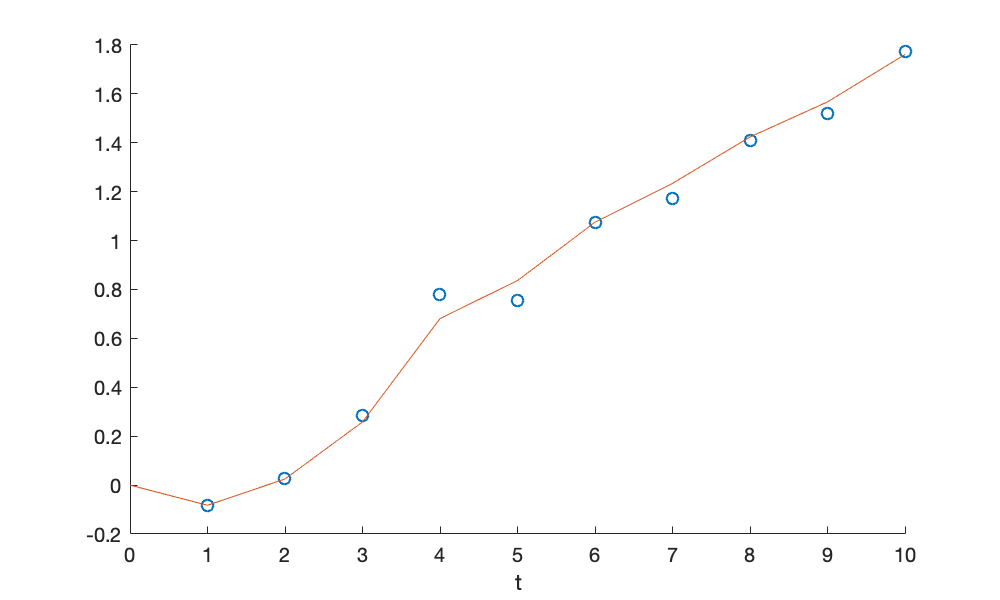

dt=1; nt=length(t); 
q=0.001; A=[1 dt;0 1]; Q=diag([0,q*dt]);  H=[1 0]; R=0.1^2; 
m0=[0;0]; P0=eye(2);    
Ma=[ ]; m=m0; P=P0;  
for k=1:nt
    m=A*m; P=A*P*A'+Q;
    S=H*P*H'+R; K=P*H'/S; P=P-K*S*K'; m=m+K*(y(k)-H*m);
    Ma(k)=m(1); % position estimate
end
plot(t,y,'o',[0 t],[m0(1) Ma])
xlabel('t'), box off

The 95% confidence interval of position (the first state component) is $m_{10|10}(1) \pm 1.96\sqrt{P_{10|10}(1,1)}$. 

m(1)+[-1,1]*1.96*sqrt(P(1,1))

ans =     1.6154    1.9070


### Part (b)

The distribution of $x_{11}\mid y_{1:10}$ is found by applying a prediction step.

m=A*m; P=A*P*A'+Q;
m(1)+[-1,1]*1.96*sqrt(P(1,1))

ans =     1.7279    2.1641


At $t=11$ there is no measurement, so we omit the update step and make another prediction step to find the distribution of $x_{12}\mid y_{1:10}$.

m=A*m; P=A*P*A'+Q;
m(1)+[-1,1]*1.96*sqrt(P(1,1))

ans =     1.8179    2.4437


### Part (c)

The  Kalman gain computed after 10 time steps is

K

K =     0.5533
    0.2116


We can use this as an approximation of the steady-state gain in the steady-state filter. 

Alternatively, we can use the solution of the Riccati equation.

X=dare(A',H',Q,R); S=H*X*H'+R; K=X*H'/S, P=X-K*S*K';

K =     0.5531
    0.2114


Steady state Kalman filter   

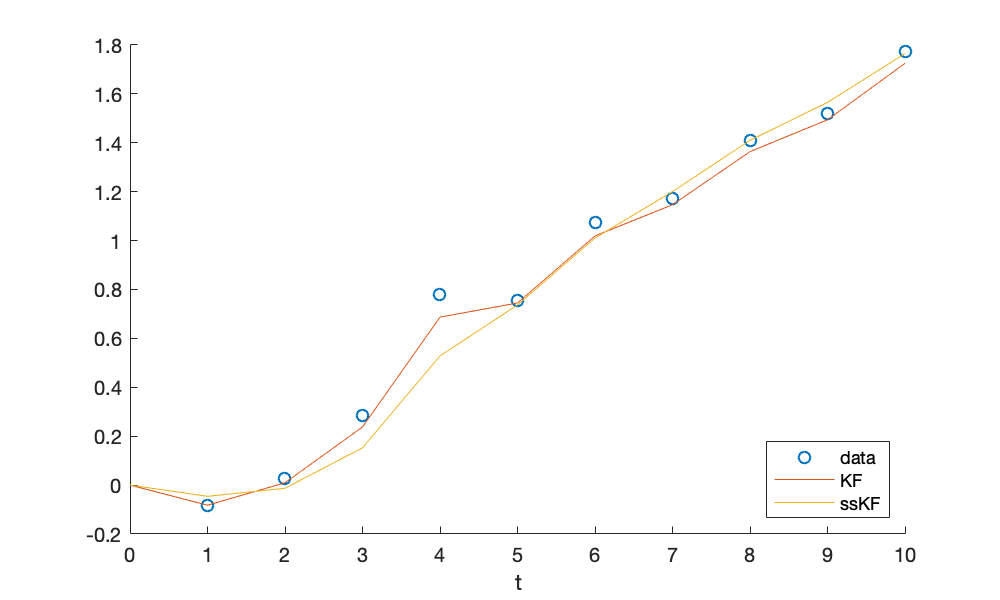

Mss=[ ]; m=m0;   
for k=1:nt
    m=A*m; 
    m=m+K*(y(k)-H*m);
    Mss(k)=m(1); % position estimate
end
plot(t,y,'o',[0 t],[m0(1) M],[0 t],[m0(1) Mss])
xlabel('t'), box off, legend('data','KF','ssKF','location','southeast')

Confidence interval of position estimate. 

m(1)+[-1,1]*1.96*sqrt(P(1,1))

ans =     1.6191    1.9106


### Part (d)

The random walk model has a single state. The model is

A=1; Q=0.2^2; H=1; m0=0; P0=1;  

Kalman filter. The path estimated with the random walk model is not as smooth as the path estimated with the integrated random walk model.

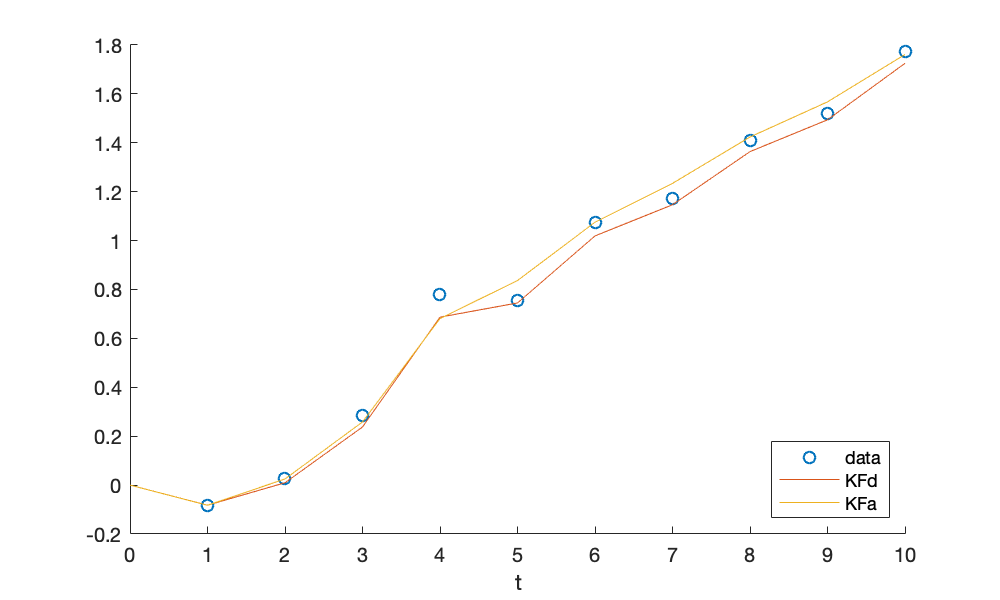

Md=[ ]; m=m0; P=P0;  
for k=1:nt
    m=A*m; P=A*P*A'+Q;
    S=H*P*H'+R; K=P*H'/S; P=P-K*S*K'; m=m+K*(y(k)-H*m);
    Md(k)=m(1); % position estimate
end
plot(t,y,'o',[0 t],[m0(1) Md],[0 t],[m0(1) Ma])
legend('data','KFd','KFa','location','southeast')
xlabel('t'), box off

Confidence interval for position at t=10

m(1)+[-1,1]*1.96*sqrt(P(1,1))

ans =     1.5467    1.9035


Confidence intervals for position at t=11 and t=12. The predicted position stays constant after the last measurement (random walk has constant mean) but the interval width increases.

m=A*m; P=A*P*A'+Q;  % predict one step ahead
m(1)+[-1,1]*1.96*sqrt(P(1,1))

ans =     1.2945    2.1558


m=A*m; P=A*P*A'+Q;  % predict next step ahead
m(1)+[-1,1]*1.96*sqrt(P(1,1))

ans =     1.1428    2.3075
